clear; clc; close all;
set(groot, 'defaultLegendInterpreter','latex'); 

# Hopping Robot Modeling and Simulation

**Last modified: **June 9, 2021

**Author: **Bradley Kwan

**Description: **The following MATLAB script defines the physical parameters of the leg and runs them in the Simulink model where the equations are defined in a function.

**Necessary Files:**

- `HR_Stateflow_Control.slx: `The Simulink model which contains the Stateflow model for the hopping robot.

## Defining Physical Parameters

This section will focus on defining the lengths and masses for the leg.

L1 = .3;    % Thigh link length [m]
L2 = .3;    % Shank link length [m]
m1 = .2;   % Thigh link mass [kg]
m2 = .2;   % Shank link mass [kg]
M = .7;    % Hip mass [kg]
physParam = [L1, L2, m1, m2, M];

% Mass moment of inertia of respective links
I1 = 1/12*m1*L1^2;
I2 = 1/12*m2*L2^2;
% Gravitational acceleration [m/s^2]
g = 9.81;
massTot = M + m1 + m2;
constgrav = massTot*g;

## Selecting Initial Conditions

The following section sill define the intial joint positions and velocities.

% Theta 1 initial position [rad]
th1o = pi/6;
% Theta 2 initial position [rad]
th2o = -pi/6;

% Initial height of robot [m]
initHeight = .7;
ydo = 0;

## Calculating Location of Center of Mass

The assumption will be made that the foot does not slip during the stance phase (when the foot is in contact with the ground). For this reason, the knee position must be calculated for the knee joint angle and the hip location is calculated based on the location of the knee. 

ym1  = L1/2*cos(th1o)+L2*cos(th2o);
ym2  = L2/2*cos(th2o);
yhip = L2*cos(th2o) + L1*cos(th1o);

The next lines of code will determine the location of the center of mass of the robot

yCMo = 1/massTot*(m1*ym1+m2*ym2+M*yhip);

The first variables defined are the constant torques applied to the leg. 

tau1 = -5;
tau2 = 5;

#### Defining Controller Gains

Here is where the gains for the PID controller in the flight phase are defined.

Pgain = 15;
Igain = 0;
Dgain = 12;

## Running the Simulation

Once the torques and configuration are defined, the model can be run.

simout = sim('HR_Stateflow_Control.slx');

Next, assign data output to variables

th1  = simout.theta(:,1);
th2  = simout.theta(:,2);
th1d = simout.thetad(:,1);
th2d = simout.thetad(:,2);

## Calculating Location of Leg

The assumption will be made that the foot does not slip during the stance phase (when the foot is in contact with the ground). For this reason, the knee position must be calculated for the knee joint angle and the hip location is calculated based on the location of the knee. 

yhip  = simout.yhip;
yfoot = simout.yfoot;
yknee = simout.yhip - L1*cos(th1);
xhip  = zeros(1,length(simout.tout))';
xknee = L1*sin(th1); 
xfoot = xknee + L2*sin(th2);
xm1 = L1/2*sin(th1);
ym1 = L1/2*cos(th1)+L2*cos(th2);
xm2 = L1*sin(th1)+L2/2*sin(th2);
ym2 = L2/2*cos(th2);
distL1 = ((xknee-xhip).^2+(yknee-yhip).^2).^(1/2);
distL2 = ((xknee-xfoot).^2+(yknee-yfoot).^2).^(1/2);

The next lines of code will determine the location of the center of mass of the robot

xcm = 1/massTot*(m1*xm1+m2*xm2+M*xhip);
ycm = 1/massTot*(m1*ym1+m2*ym2+M*yhip);

## Plotting Leg Attributes against Time

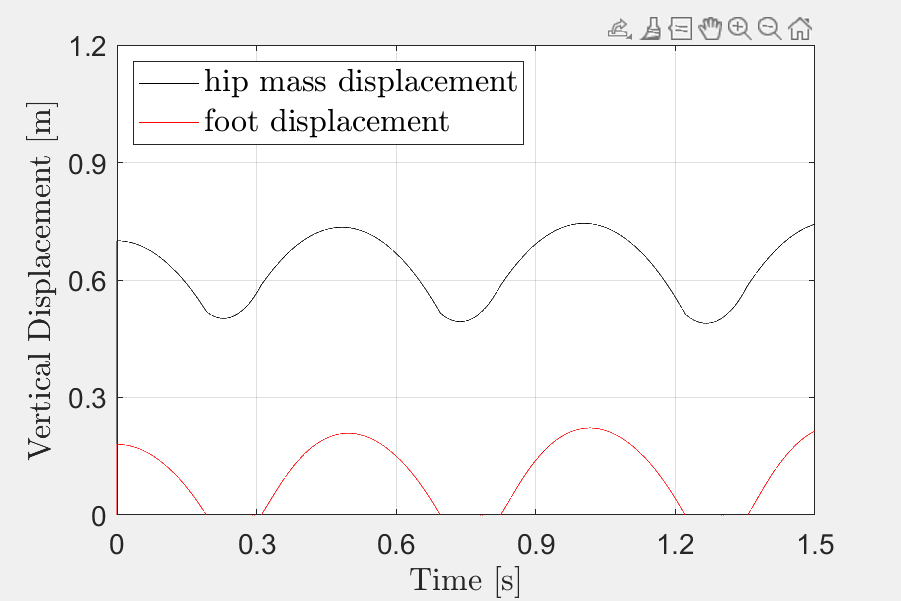

legplot = figure;
legplot.Visible = 'on';
hold on
plot(simout.tout,simout.yhip,'k')
plot(simout.tout,simout.yfoot,'r')
hold off
ax = gca;
ax.FontSize = 14;
xlabel('Time [s]','Interpreter','Latex','FontSize',16)
ylabel('Vertical Displacement [m]','Interpreter','Latex','FontSize',16)
legend('hip mass displacement','foot displacement','Location',"northwest",'FontSize',16)
axis([0 1.5 0 1.2])
grid on; box on;
xticks([0:.3:1.5]); yticks([0:0.3:1.2]);
set(gcf,'position',[0 0 600 400])

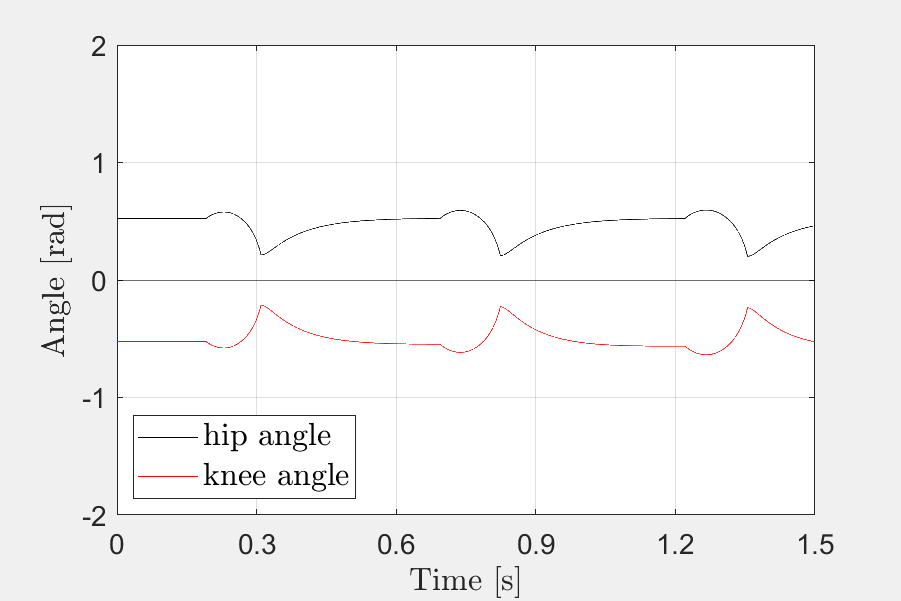

angplot = figure;
angplot.Visible = 'on';
hold on
plot(simout.tout,simout.theta(:,1),'k')
plot(simout.tout,simout.theta(:,2),'r')
plot([0 max(simout.tout)], [0 0],'k')
hold off
ax = gca;
ax.FontSize = 14;
xlabel('Time [s]','Interpreter','Latex','FontSize',16)
ylabel('Angle [rad]','Interpreter','Latex','FontSize',16)
legend('hip angle','knee angle','Location',"southwest",'FontSize',16)
axis([0 1.5 -2 2])
xticks([0:.3:1.5]); yticks([-2:2]);
grid on; box on;
set(gcf,'position',[0 0 600 400])
print(gcf, 'const_displacement.pdf', '-dpdf', '-loose')

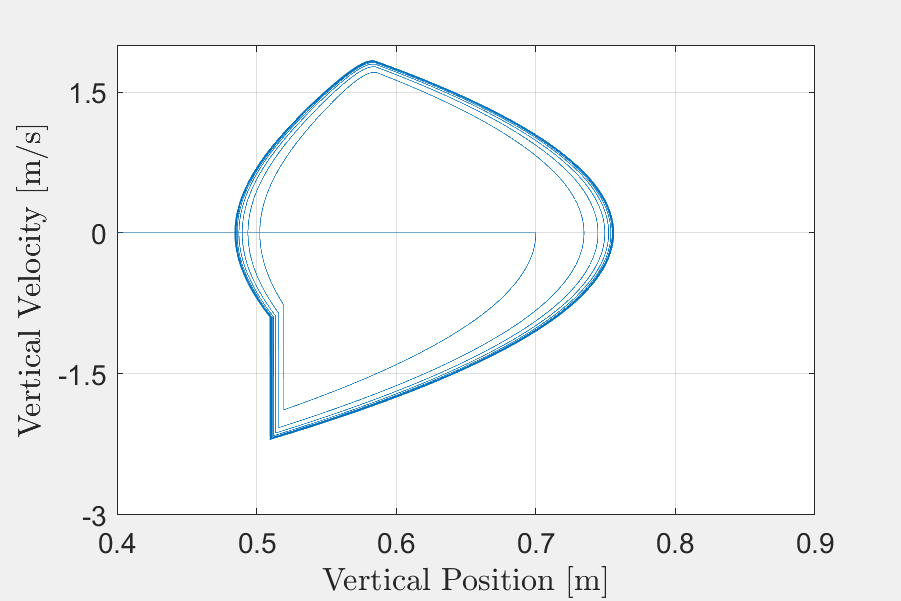

phasetraj = figure;
phasetraj.Visible = 'on';
plot(simout.yhip,simout.ydCM)
ax = gca;
ax.FontSize = 14;
xlabel('Vertical Position [m]','Interpreter','Latex','FontSize',16)
ylabel('Vertical Velocity [m/s]','Interpreter','Latex','FontSize',16)
grid on; box on;
set(gcf,'position',[0 0 600 400]);
xlim([.4 .9]); xticks([.4:.1:.9]);
yticks([-3:1.5:3]);

GRFfig = figure;
GRFfig.Visible = 'on';
hold on
plot(simout.tout,simout.GRF,'k');
hold off
ylim([0 50]); yticks([0:10:50])
grid on; box on;
ax = gca;
ax.FontSize = 14;
xlabel('Time [s]','Interpreter','Latex','FontSize',16); 
ylabel('Vertical Component of GRF [N]','Interpreter','Latex','FontSize',16);
xlim([.9 1.3]); xticks([.9:.1:1.3]);
legend('SimScape Multibody Results','Simulink Stateflow Results','Location',"northeast",'FontSize',12)

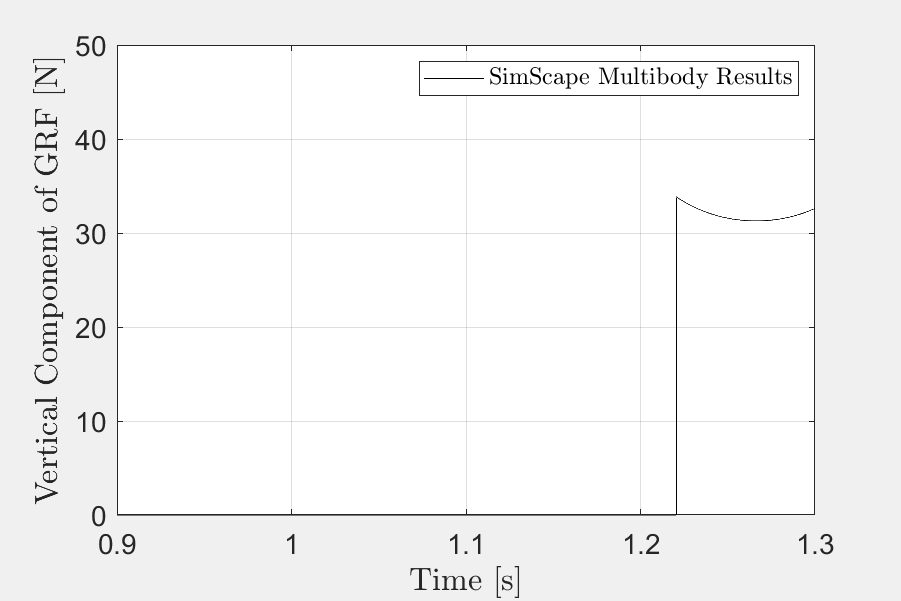

set(gcf,'position',[0 0 600 400])

## Animating the Leg

By animating the results, researchers can see the motion of the leg during the stance state.

First we must post process the results to produce a smoother animation.

fps = 60;
t = 0:1/fps:max(simout.tout);
xknee = interp1(simout.tout,xknee,t);
xhip = interp1(simout.tout,xhip,t);
xfoot = interp1(simout.tout,xfoot,t);
yknee = interp1(simout.tout,yknee,t);
yhip = interp1(simout.tout,simout.yhip,t);
yfoot = interp1(simout.tout,yfoot,t);

The next lines of code create the animation.

legGif = figure;
legGif.Visible = 'on';
ax = axes;
axis([-1 1 -.2 1.2]); xticks([-1:.5:1]); yticks([0:.3:1.2]);
hold on;
traject = animatedline('color','r','MaximumNumPoints', 15,'LineWidth',2);
p = plot(xhip,yhip,'ks', 'LineWidth',30,'MarkerSize',20);
area([-1 1],[-.2 -.2],'FaceColor',[.5 .5 .5])
leg = plot([xhip xknee xfoot],[yhip yknee yfoot],'b-','LineWidth',5);
ax = gca;
ax.FontSize = 14;
set(gcf,'position',[0 0 600 400]);
xlabel('Horizontal Position [m]','Interpreter','Latex','FontSize',16);
ylabel('Vertical Position [m]','Interpreter','Latex','FontSize',16);
grid on; box on;
hold off

The following `for` loop is used to refresh the plot for every tick of time defined earlier by the desired fps.

Error using getframe
A valid figure or axes handle must be specified

for n = 1:length(t)
    p.XData = xhip(n);
    p.YData = yhip(n);
    leg.XData = [xhip(n) xknee(n) xfoot(n)];
    leg.YData = [yhip(n) yknee(n) yfoot(n)];
   
    addpoints(traject,xhip(n),yhip(n));
    drawnow
    
    frame = getframe(legGif);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    
    if n == 1
        imwrite(imind,cm,'leg_locomotion_offset.gif','gif','LoopCount', inf,'DelayTime',1/fps);
    elseif n == length(t)
        imwrite(imind,cm,'leg_locomotion_offset.gif','gif','WriteMode','append','DelayTime',5/fps);
    else
        imwrite(imind,cm,'leg_locomotion_offset.gif','gif','WriteMode','append','DelayTime',1/fps);
    end
end